# **JanusDAS Workflow**

**version 2.2.1**

*Feburary 21, 2022*

### **1. READ POINTCLOUD FILE**

**pointcloud file = 210815_Pit_merged.laz**

merged laz file of the following files: 

- 210815_Pit_MD-0-1.las

- 210815_Pit_MD-0-2.las

- 210815_Pit_MD-0-3.las

- 210815_Pit_MD-1-0.las

- 210815_Pit_MD-1-1.las

- 210815_Pit_MD-1-2.las

- 210815_Pit_MD-1-3.las

- 210815_Pit_MD-1-4.las

inputlaz = '/home/mark/Development/input/210815_Pit_merged.laz';
lasReader = lasFileReader(inputlaz);
ptCloud = readPointCloud(lasReader);

ptCloud = pointCloud(ptCloud.Location(:, [2 1 3]));

### 2. DOWNSAMPLE POINTCLOUD

gridstep = 0.5

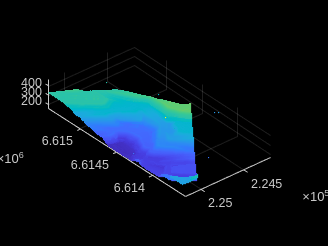

gridStep = 0.5;
ptCloudDown = pcdownsample(ptCloud, 'gridAverage', gridStep);
% clear ptCloud;

figure;
pcshow(ptCloudDown.Location);

view([-130 33])

### 3. REMOVE NOISE

numNeighbors = 4, threshold = 1

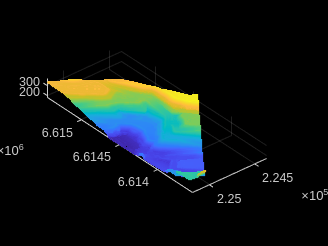

numNeighbors = 4;
threshold = 1;
ptCloudDenoised = pcdenoise(ptCloudDown, 'NumNeighbors', numNeighbors, 'Threshold', threshold);
xlimits = double(ptCloudDenoised.YLimits);
ylimits = double(ptCloudDenoised.XLimits);
% clear ptCloudDown;

figure;
pcshow(ptCloudDenoised.Location);

view([-130 33])

### 3. CREATE DEM FROM POINTCLOUD

gridSize = 0.5

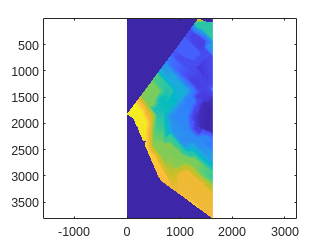

gridSize = 0.5;
epsgCode = 7856;
outputName = '210815_Pit_merged';

terrainModel = pc2dem(ptCloudDenoised, gridSize);
terrainModel = flipud(rot90(terrainModel));
rasterSize_dem = [size(terrainModel)];
R_dem = maprefcells(xlimits,ylimits,rasterSize_dem);
coordRefSysCode = epsgCode; % EPSG:7856 GDA2020 / MGA Zone 56
demFile = strcat(outputName, '_dem.tif');
geotiffwrite(demFile, terrainModel, R_dem, 'CoordRefSysCode', coordRefSysCode);

figure;
imagesc(terrainModel);
axis equal;

### 4. GET GROUND POINTS

maxWindowRadius  = 16, elevationThreshold = 0.1, slopeThreshold = 0.1, elevationScale = 1.5

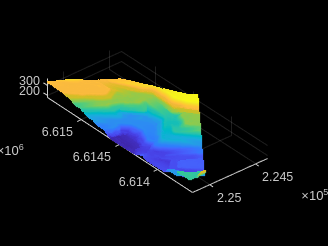

maxWindowRadius  = 16;
elevationThreshold = 0.1;
slopeThreshold = 0.1;
elevationScale = 1.5;
[groundPtsIdx, nonGroundPtCloud, groundPtCloud] = segmentGroundSMRF(ptCloudDenoised, 'MaxWindowRadius', maxWindowRadius, ...
        'ElevationThreshold', elevationThreshold, 'SlopeThreshold', slopeThreshold, 'ElevationScale', elevationScale);

figure;
pcshow(groundPtCloud.Location);

view([-130 33])

### 5. FILTER OUT AREAS WITH HIGH PERCENT SLOPE 

`slopePercent = 12`

`localPlaneFitting = 10`

slopePercent = 12;
localPlaneFitting = 10;
normalFilter = cos(atan(slopePercent/100));
normals = pcnormals(groundPtCloud, localPlaneFitting);
filteredNormals = find(normals(:,3) > normalFilter);
filteredGround = select(groundPtCloud, filteredNormals);
% clear groundPtCloud;
% clear nonGroundPtCloud;